# **FIT EMPIRICAL BETA PARAMETERS: **$\beta_{fit.Dp}(D_p)$**:**

  An empirical expression for $\beta_{fix.fit.Dp}(D_p)$ is calculated from the output data indluded in tables DATA_FIT_I_DG*_ACAP. Calculated values $\beta_i$ on each point of the WRC for each sample  are included in each record of DATA_FIT_I_DG*_ACAP, $\beta_i$ is fitted against values of previously fitted parameter $\beta_{fix.fit}$(calculated with the empirical expression already fitted) and with values of $\log D_p$ for each point of the WRC.

## **Option Dg0=1: Empirical expression for **$\beta_{fix.fit,Dp}(Dp)$**for **$D_{g0}=D_{50}/1mm$

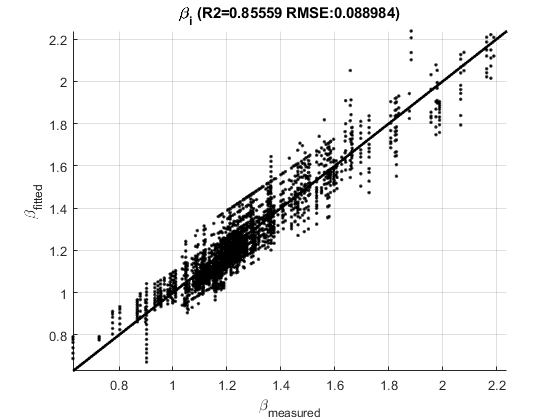

beta_fix.fit.Dp =-0.092664-0.029338.*LOGDPI+0.672826.*BETA_FIX_FIT-0.011744.*LOGDPI:BETA_FIX_FIT


% Comment: Data input DATA_INPUT must be present and then the tables with results need to be generated or loaded with scripts: 
% load('DATA_ACAP.mat', 'DATA_INPUT');
% script_ACAP_Get_Results_Tables;
% script_AP81_Get_Result_Tables
% script_AP99_Get_Result_Tables
% script_AP08_Get_Result_Tables;
% script_CNEAP_Get_Result_Tables
%
% Or load data and results from DATA_ACAP.mat:
load('DATA_ACAP.mat');
DATA_I = DATA_FIT_I_DG1_ACAP(DATA_FIT_I_DG1_ACAP.INTO_BOUND==1,:);
disp(func_ACAP_fit_beta_Dp(DATA_I,'BETAI ~ LOGDPI*BETA_FIX_FIT','beta_fix.fit.Dp'));

## **Option Dg0=2: Empirical expression for **$\beta_{fix.fit,Dp}(Dp)$**for **$D_{g0}=D_{50}/0.075mm$:

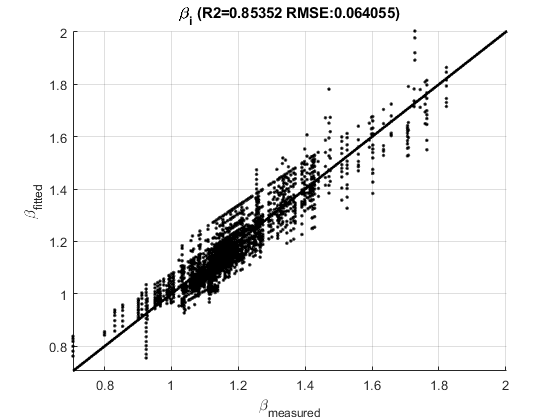

beta_fix.fit.Dp =+0.063253-0.016464.*LOGDPI+0.619926.*BETA_FIX_FIT-0.014795.*LOGDPI:BETA_FIX_FIT


DATA_I = DATA_FIT_I_DG2_ACAP(DATA_FIT_I_DG2_ACAP.INTO_BOUND==1,:);
disp(func_ACAP_fit_beta_Dp(DATA_I,'BETAI ~ LOGDPI*BETA_FIX_FIT','beta_fix.fit.Dp'));

## **Option Dg0=3: Empirical expression for **$\beta_{fix.fit,Dp}(Dp)$**for **$D_{g0}=D_{50}/0.002mm$:

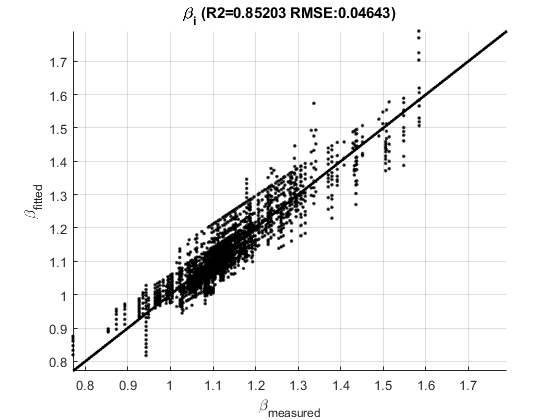

beta_fix.fit.Dp =+0.167522-0.007437.*LOGDPI+0.594918.*BETA_FIX_FIT-0.016102.*LOGDPI:BETA_FIX_FIT


DATA_I = DATA_FIT_I_DG3_ACAP(DATA_FIT_I_DG3_ACAP.INTO_BOUND==1,:);
disp(func_ACAP_fit_beta_Dp(DATA_I,'BETAI ~ LOGDPI*BETA_FIX_FIT','beta_fix.fit.Dp'));

## **Option Dg0=4: Empirical expression for **$\beta_{fix.fit,Dp}(Dp)$**for **$$D_{g0}=\sqrt[3]{2650}$$:

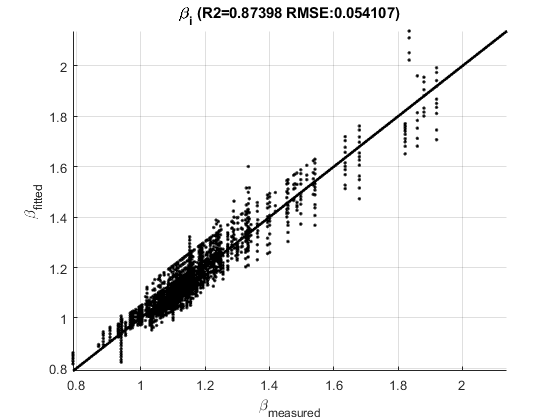

beta_fix.fit.Dp =+0.232958+0.005403.*LOGDPI+0.546931.*BETA_FIX_FIT-0.026727.*LOGDPI:BETA_FIX_FIT


DATA_I = DATA_FIT_I_DG4_ACAP(DATA_FIT_I_DG4_ACAP.INTO_BOUND==1,:);
disp(func_ACAP_fit_beta_Dp(DATA_I,'BETAI ~ LOGDPI*BETA_FIX_FIT','beta_fix.fit.Dp'));

## **Option Dg0=5: Empirical expression for **$\beta_{fix.fit,Dp}(Dp)$**for **$$D_{g0}=1$$:

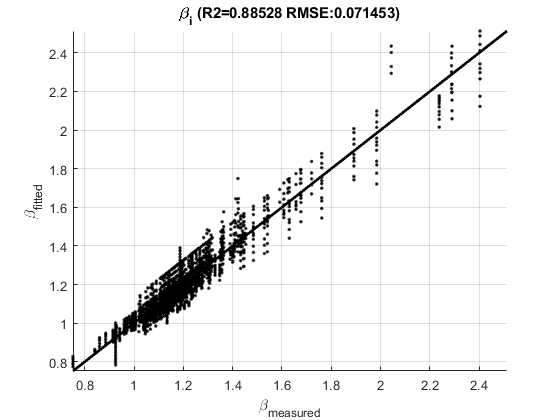

beta_fix.fit.Dp =+0.159121+0.001285.*LOGDPI+0.575382.*BETA_FIX_FIT-0.026652.*LOGDPI:BETA_FIX_FIT


DATA_I = DATA_FIT_I_DG5_ACAP(DATA_FIT_I_DG5_ACAP.INTO_BOUND==1,:);
disp(func_ACAP_fit_beta_Dp(DATA_I,'BETAI ~ LOGDPI*BETA_FIX_FIT','beta_fix.fit.Dp'));

clear('DATA_I');